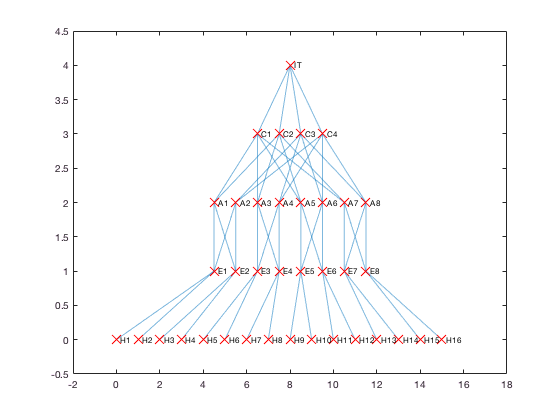

k=4;

%Compute values for topology
assert(mod(k,2)==0,'Error, k must be an even number.')
core=(k/2)^2;
pods=core/2;
aggregation=core*2;
host_per_aggregation=(k^3/4)/aggregation;
variable_names_node_table = {'EndNodes';'Xpoint';'Ypoint';'Layer'};

%Compute values for plotting
differenceX=1;
startX=0; %Compute startX as the difference between total width and width of present layer divided by 2.
differenceY=1;
startY=4;
width=aggregation*host_per_aggregation*differenceX;

%Preallocation
h=aggregation*2+aggregation*host_per_aggregation+core+1;
endnodes = cell(h, 1);
Xpoint(h,1)=1;
Ypoint(h,1)=1;
layern(h,1)=1;
edges(core+aggregation*pods*2+aggregation*host_per_aggregation,2)=1;

%Internet layer
Xpoint(1,1)=width/2;
Ypoint(1,1)=startY;
layern(1)=0;
endnodes{1}='IT';

%Ypoint=zeros(h,1)+ones(h-aggregation*host_per_aggregation,1)+ones(core+1+aggregation,1)+ones(core+1,1)+ones(1,1)

%Core layer
startX=(width-(core-1)*differenceX)/2;
startY=startY-1;
for i=1:core
    Ypoint(i+1,1)=startY;
    Xpoint(i+1,1)=startX+differenceX*(i-1);
    layern(i+1)=1;
    endnodes{i+1} = strcat('C', num2str(i));
    edges(i,1)= 1;
    edges(i,2)= i+1;
end

%Aggregation layer
posedge=i;
posnode=i+1;
startY=startY-1;
startX=(width-(aggregation-1)*differenceX)/2;
count=1;
for i=1:aggregation
    Ypoint(posnode+i,1)=startY;
    layern(posnode+i,1)=2;
    Xpoint(posnode+i,1)=startX+differenceX*(i-1);
    endnodes{posnode+i} = strcat('A', num2str(i));
    extra=(mod(i,2)==0);
    for j=2:pods+1
        edges(posedge+count,1)=posnode+i;
        edges(posedge+count,2)= j+extra*pods;
        count=count+1;
    end
end

%Edge layer
posedge=posedge+count-1;
posagg=posnode;
posnode=posnode+i;
startY=startY-1;
startX=(width-(aggregation-1)*differenceX)/2;
count=1;
for i=1:aggregation
    Ypoint(posnode+i,1)=startY;
    layern(posnode+i,1)=3;
    Xpoint(posnode+i,1)=startX+differenceX*(i-1);
    endnodes{posnode+i} = strcat('E', num2str(i));
    extra=int32(i/pods)-1;
    for j=1:pods
        edges(posedge+count,1)=posnode+i;
        edges(posedge+count,2)= posagg+j+extra*pods;
        count=count+1;
    end
end

%Host layer
posedge=posedge+count-1;
posnode=posnode+i;
posagg=posagg+aggregation;
startY=startY-1;
startX=0;
count=1;
count2=1;
for j=1:aggregation
    for i=1:host_per_aggregation
        Ypoint(posnode+count,1)=startY;
        layern(posnode+count,1)=4;
        Xpoint(posnode+count,1)=startX+differenceX*(count-1);
        endnodes{posnode+count} = strcat('H', num2str(count));
        edges(posedge+count,1)=posagg+j;
        edges(posedge+count,2)=posnode+i+(count2-1)*host_per_aggregation;
        count=count+1;
    end
    count2=count2+1;
end

layer=categorical(layern,0:4,{'internet' 'core' 'aggregation' 'edge' 'host'});
NodeTable=table(endnodes,Xpoint,Ypoint,layer,'VariableNames',variable_names_node_table);
EdgeTable=table(edges,'VariableNames',{'EndNodes'});
G=graph(EdgeTable,NodeTable);
plotGraphtopology(G);